# Estimation of elastic properties of KOQ_HTI sample

**Author**: Martin Rühlmann, Abakumov Ivan

**Publication date**: 24th October 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

Some bla bla bla here))

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## 1. Upload the data

Sample = MLD('/remote/data/ivan/Ultrasonic_data/KOQ-HTI/Sample_KOQ_HTI_data.mat');

% Data = load('/remote/data/ivan/Ultrasonic_data/KOQ-HTI/Processed/KOQ_HTI_PR.txt'); 
% Sample.Theta  = Data(:,1);     % beta  [DEG] Grad
% Sample.Vp33 = Data(:,2);       % P-velocity in vertikaler (axial) "slow"
% Sample.Vp11 = Data(:,3);       % P-velocity horizontal (radial) "fast"
% Sample.Vs31 = Data(:,4);       % S-velocity vertical  (axial) "slow"
% Sample.Vs21 = Data(:,5);       % S-velocity horizontal  (radial) "fast"
% Sample.Vqp = Data(:,6);
% Sample.rho = 2.205;

ind1 = 1:8;             % seria of measurements 
ind2 = 9:16;            % another at 90 degree

## Plot velocities

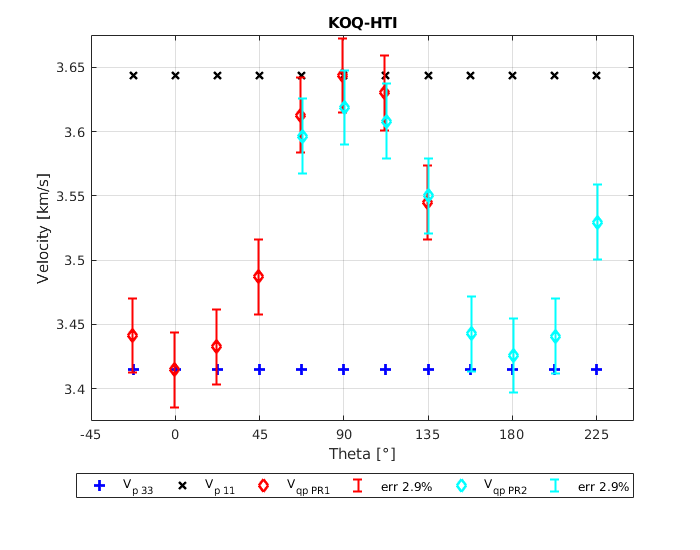

figure(123)       % P velocities
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'Location', 'southoutside', 'Orientation','horizontal')
title('KOQ-HTI')
xticks(-45:45:270)
xticklabels(-45:45:270)
axis([-45 245 3.375 3.675]);
grid on

## 2. Conventional analyses of Thomsen's parameters

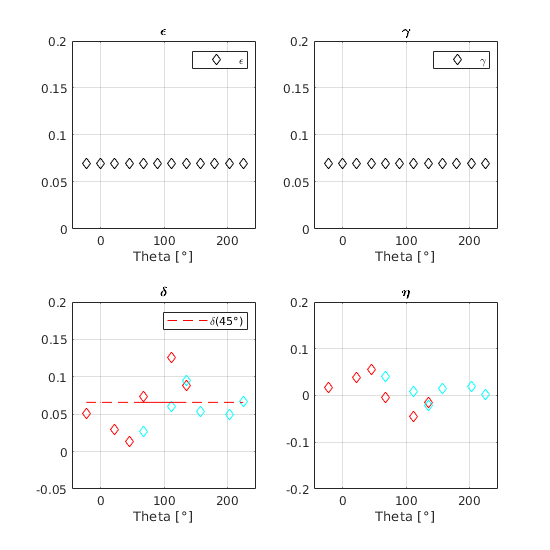

C11 = Sample.rho*Sample.Vp11.^2;
C33 = Sample.rho*Sample.Vp33.^2; 
C44 = Sample.rho*Sample.Vs31.^2; 
C66 = Sample.rho*Sample.Vs21.^2; 
Cqp = Sample.rho*Sample.Vqp.^2;
C12 = C11 - 2*C66;

ST2 = (sin(Sample.Theta/180*pi)).^2; 
CT2 = (cos(Sample.Theta/180*pi)).^2; 

A = (C11 + C44).*ST2 + (C33 + C44).*CT2; 
B = (C11 - C44).*ST2 - (C33 - C44).*CT2; 

C13 = sqrt(((2*Cqp-A).^2 - B.^2)./(4*ST2.*CT2)) - C44;

gamma   = (C66 - C44)./(2*C44);
epsilon = (C11 - C33)./(2*C33);
delta = ((C13+C44).^2 - (C33-C44).^2)./(2*C33.*(C33-C44));
eta = (epsilon-delta)./(1+2*delta);

ind = ((Sample.Theta == 45) + (Sample.Theta == 135) + (Sample.Theta == 225)) == 1;
delta45.mean = mean(delta(ind)); 
delta45.std = std(delta(ind)); 


figure(21);
fig = figure('Position', [1 1 550 550]);

subplot(2,2,1)
plot(Sample.Theta,epsilon,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([-45 245 0 0.2]);
legend('\epsilon')
grid on
title('\epsilon')

subplot(2,2,2)
plot(Sample.Theta,gamma,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([-45 245 0 0.2]);
legend('\gamma')
grid on
title('\gamma')

subplot(2,2,3)
l1 = plot(Sample.Theta(ind1),delta(ind1),'rd'); 
hold on
l2 = plot(Sample.Theta(ind2),delta(ind2),'cd'); 
ll = plot(Sample.Theta,delta45.mean*ones(size(Sample.Theta)),'r--'); 
legend(ll, '\delta(45\circ)')
xlabel('Theta [\circ]','LineWidth', 2)
axis([-45 245 -0.05 0.2]);
grid on
title('\delta')

subplot(2,2,4)
plot(Sample.Theta(ind1),eta(ind1),'rd'); 
hold on
plot(Sample.Theta(ind2),eta(ind2),'cd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([-45 245 -0.2 0.2]);
grid on
title('\eta')

## 3. Least squares analysis of Thomsen's parameters

### Visualize the data

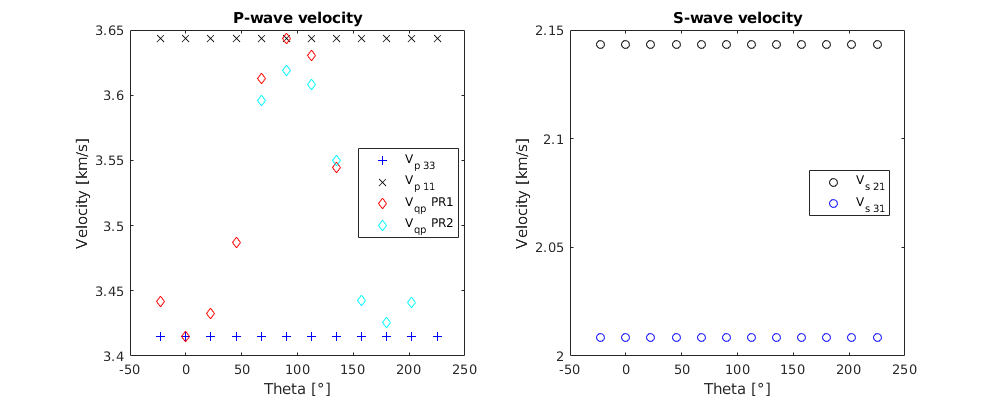

figure(122)
fig = figure('Position', [1 1 1000 400]);
subplot(1,2,1)
plot(Sample.Theta, Sample.Vp33, '+b');
hold on
plot(Sample.Theta, Sample.Vp11, 'xk');
plot(Sample.Theta(ind1), Sample.Vqp(ind1), 'dr');
plot(Sample.Theta(ind2), Sample.Vqp(ind2), 'dc');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{p 33}', 'V_{p 11}', 'V_{qp} PR1', 'V_{qp} PR2','Location','best')
title('P-wave velocity')

subplot(1,2,2)
plot(Sample.Theta, Sample.Vs21, 'ko');
hold on 
plot(Sample.Theta, Sample.Vs31, 'bo');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{s 21}','V_{s 31}','Location','best')
title('S-wave velocity')

### Assign C values

Sample.C11 = C11;
Sample.C33 = C33;
Sample.C44 = C44;
Sample.C66 = C66;
Sample.Vqp = Sample.Vqp;

### Find optimum delta

testdelta = -0.3:0.0001:0.5;
dtheta = -10:0.1:10;
nSample = Sample; 
JJ = zeros(length(dtheta),length(testdelta));
for i=1:length(dtheta)
    nSample.Theta = Sample.Theta + dtheta(i);
    J = costFunction_delta(nSample,testdelta);
    JJ(i,:) = J; 
end

[~, minind] = min(JJ(:));
[inda, indd] = ind2sub(size(JJ),minind);
 
thetapl = dtheta(inda);
delta = testdelta(indd);

### Plot final results 

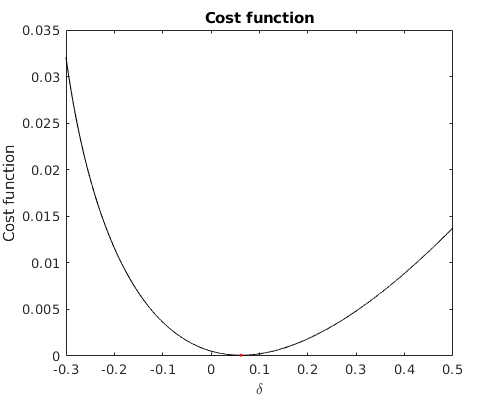

figure(343)
fig = figure('Position', [1 1 500 400]);
plot(testdelta, JJ(inda,:), 'k-');
hold on 
plot(testdelta(indd), JJ(inda,indd), 'r.','MarkerSize', 7);
xlabel('\delta')
ylabel('Cost function')
title('Cost function')

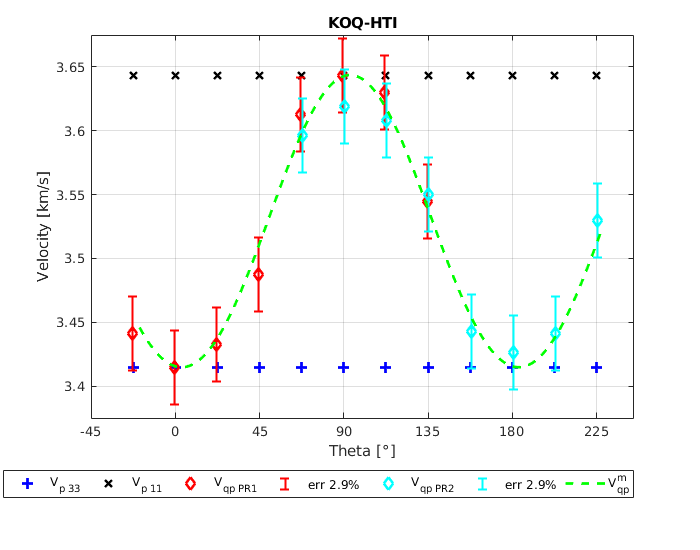


nSample.Theta = -22.5:1:225;
Vqp = get_Vqp_VTI(nSample,delta);
 
figure(1222)
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
plot(nSample.Theta-thetapl, Vqp, 'g--', 'LineWidth', 2)
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'V_{qp}^m', 'Location', 'southoutside', 'Orientation','horizontal')
title('KOQ-HTI')
xticks(-45:45:270)
xticklabels(-45:45:270)
axis([-45 245 3.375 3.675]);
grid on

## 3. Least squares analysis of Thomsen's parameters (weak anisotropy approximation)

Alpha   = linspace(3.3,3.5,101);
Delta   = linspace(-0.05,0.2,51);
Epsilon = linspace(0.02,0.12,21);
dTheta  = linspace(-10,10,51);


tic
J = costFunction_delta_weak(Sample,Alpha,Delta,Epsilon,dTheta);
toc

Elapsed time is 6.387254 seconds.



[~, ind] = min(J(:));
[inda,indd,inde,indt] = ind2sub(size(J),ind);

result.alpha = Alpha(inda);
result.delta = Delta(indd);
result.epsilon = Epsilon(inde);
result.dtheta = dTheta(indt);

## Plot the result:

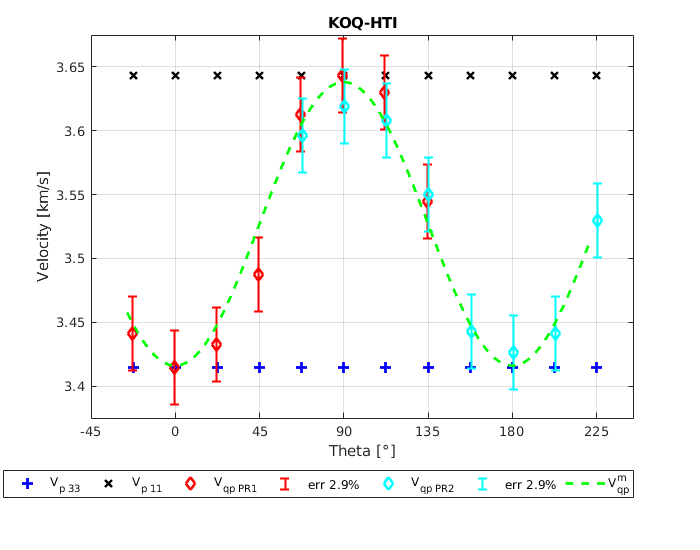

figure(27)
fig = figure('Position', [1 1 1200 800]);

nSample.Theta = -22.5:1:225;
Vqp = get_Vqp_VTI_weak(nSample,result.alpha,result.delta,result.epsilon,result.dtheta);
 

figure(144)
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
plot(nSample.Theta+result.dtheta, Vqp, 'g--', 'LineWidth', 2)
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'V_{qp}^m', 'Location', 'southoutside', 'Orientation','horizontal')
title('KOQ-HTI')
xticks(-45:45:270)
xticklabels(-45:45:270)
axis([-45 245 3.375 3.675]);
grid on

## 4. Find errors of estimated parameters

% angle error std: 3 grad  =>> error in velocity 25 m/s
% error in velocity due to measurements =>> 15 m/s
% total error: 30 m 
%                                     37 mrasurement 73
% variance for velocity error 30 m = 0.010;   0.0060
% variance for velocity error 100 m = 0.030   0.020

Theta = Sample.Theta;
iSample = Sample; 

clear test; 

for i=1:1:500

    iSample.Theta = Theta + 1*randn(size(Theta));
    Vqptrue = get_Vqp_VTI_weak(iSample,result.alpha,result.delta,result.epsilon,result.dtheta);

    VqpE = Vqptrue.*(1+0.015*randn(size(Vqptrue)));
    iSample.Vqp = VqpE; 
    iSample.Theta = Theta; 

    J = costFunction_delta_weak(iSample,Alpha,Delta,Epsilon,dTheta);

    [~, ind] = min(J(:));
    [inda,indd,inde,indt] = ind2sub(size(J),ind);

    test.alpha(i) = Alpha(inda);
    test.delta(i) = Delta(indd);
    test.epsilon(i) = Epsilon(inde);
    test.dtheta(i) = dTheta(indt);
    disp(i)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



## Plot results:

figure(33)
subplot(2,2,1); 
histfit(test.alpha',21)
xlabel('V_{P0}, [m/s]')
dist = fitdist(test.alpha(1:100)','Normal');
disp(['ALPHA: Relative error: ' num2str(abs(result.alpha-dist.mu)/result.alpha*100) '%'])

ALPHA: Relative error: 0.12763%


alpha_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,4) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,2); 
histfit(test.delta',11)
xlabel('\delta')
dist = fitdist(test.delta(1:100)','Normal');
disp(['DELTA: Relative error: ' num2str(abs(result.delta-dist.mu)/result.delta*100) '%'])

DELTA: Relative error: 12%


delta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,3); 
histfit(test.epsilon',11)
xlabel('\epsilon')
dist = fitdist(test.epsilon(1:100)','Normal');
disp(['EPSILON: Relative error: ' num2str(abs(result.epsilon-dist.mu)/result.epsilon*100) '%'])

EPSILON: Relative error: 1.8462%


epsilon_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])
%
subplot(2,2,4); 
histfit(test.dtheta',11)
xlabel('\Delta\theta')
dist = fitdist(test.dtheta(1:100)','Normal');
disp(['DTHETA: Absolute error: ' num2str(result.dtheta-dist.mu)])

DTHETA: Absolute error: -0.288


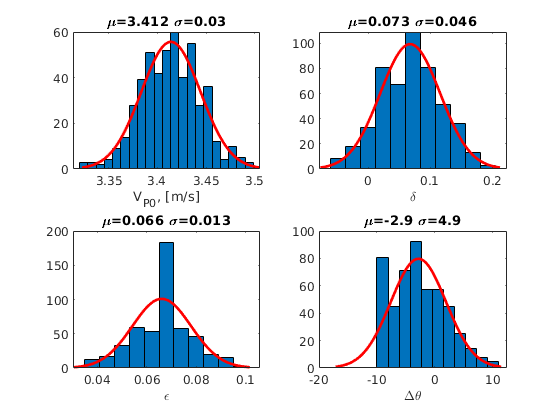

dtheta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])